clear;
clc;

imuFs = 100;
gpsFs = 10;

% GPS coords of the Oval (0, 0) point
localOrigin = [42.29356707041616 -71.26392730647744 57.0];

imuSamplesPerGPS = (imuFs/gpsFs);
assert (imuSamplesPerGPS == fix(imuSamplesPerGPS));

gndFusion = insfilterNonholonomic( ...
    'ReferenceFrame', 'ENU', ...
    'IMUSampleRate', imuFs, ...
    'ReferenceLocation', localOrigin, ...
    'DecimationFactor', 2 ...
   );

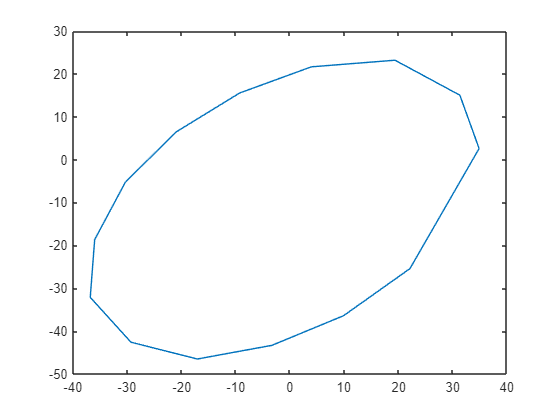

speed = 1.0; % m/s
waypoints_latlong = [
42.293185209247184, -71.26428426120886
42.29327790325564, -71.26437376918973
42.293399067360994, -71.26436392331183
42.29352023123324, -71.26429500216656
42.29362550457538, -71.2641813270246
42.29370694232076, -71.2640399044148
42.29376189618846, -71.26387968512417
42.293775800171126, -71.26369261344414
42.29370230765663, -71.2635476105151
42.293590413483365, -71.26350464668428
42.293338293121586, -71.26365921428294
42.29323930708792, -71.26380765649222
42.293177102672026, -71.26396779857141
42.29314843452921, -71.26413452183198
42.29318413447862, -71.26428442651799
    ];

localorigin_latlong = localOrigin(1:2);
waypoints_diff_from_origin = waypoints_latlong - repmat(localorigin_latlong, size(waypoints_latlong,1),1);
[waypoints_x, waypoints_y, waypoints_z] = latlon2local(waypoints_latlong(:,1),waypoints_latlong(:,2),57.0*ones(size(waypoints_latlong,1),1),localOrigin);
 
plot(waypoints_x,waypoints_y);

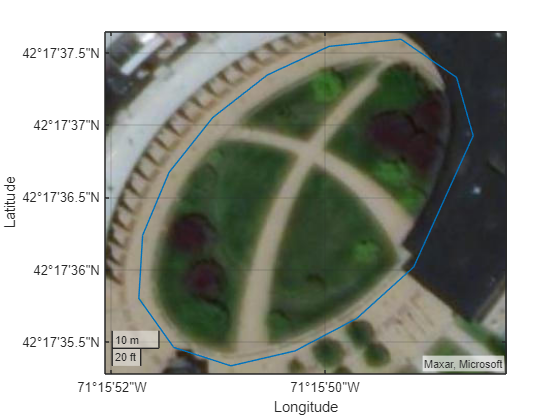


geoplot(waypoints_latlong(:,1),waypoints_latlong(:,2));
geobasemap satellite;


waypoints = [waypoints_x waypoints_y];
distance_between_waypoints = zeros(size(waypoints,1)-1,1);
for (idx=1:size(waypoints,1)-1)
    p1 = waypoints(idx,:);
    p2 = waypoints(idx+1,:);
    dist_wp = vecnorm(p2-p1);
    distance_between_waypoints(idx) = dist_wp;
end

time_between_waypoints = distance_between_waypoints/speed;

time_of_arrival_vec = [0 cumsum(time_between_waypoints)'];


traj = waypointTrajectory('Waypoints', [waypoints_x waypoints_y waypoints_z], 'TimeOfArrival', time_of_arrival_vec, 'SampleRate', imuFs);

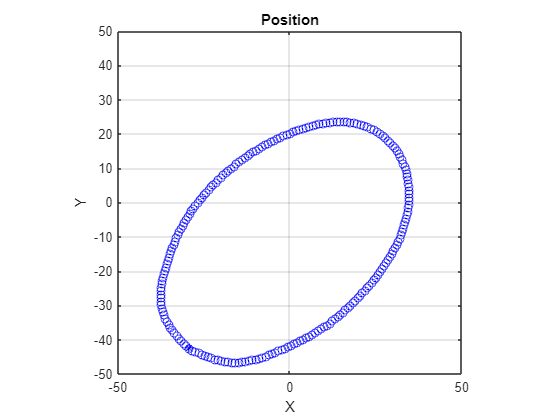

plot(waypoints(1,1),waypoints(1,2),'b*');
title("Position");
xlim([-50 50]);
ylim([-50 50]);
xlabel("X");
ylabel("Y");
axis square;
grid on;
hold on;

reset(traj);

orientationLog = zeros(ceil(time_of_arrival_vec(end)*traj.SampleRate),1,'quaternion');
posLog = zeros(ceil(time_of_arrival_vec(end)*traj.SampleRate),3);

num_pts = ceil(time_of_arrival_vec(end)*traj.SampleRate);
pos_decimate = [];
%wb = waitbar(0, 'Processing trajectory');
cnt = 0;
idx = 1;
while ~isDone(traj)
    cnt = cnt + 1;
    [pos, quat] = traj();

    

    orientationLog(idx) = quat;
    posLog(idx,:) = pos;
    
    if (cnt == imuFs)
        %waitbar(idx/num_pts,wb,'Processing trajectory');
        cnt = 0;
        pos_decimate = [pos_decimate ; pos(1) pos(2)];
        plot(pos(1),pos(2),'bo');
    end
    idx = idx + 1;
end
%close(wb);
hold off;

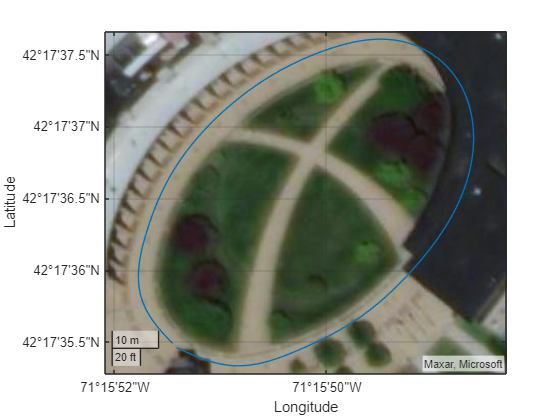

pos_decimate_3d = [pos_decimate zeros(size(pos_decimate,1),1)];
[pos_dec_lat,pos_dec_lon,pos_dec_alt] = local2latlon(pos_decimate_3d(:,1), pos_decimate_3d(:,2), pos_decimate_3d(:,3), localOrigin);
geoplot(pos_dec_lat,pos_dec_lon);
geobasemap satellite;


reset(traj);
groundTruth = traj;

%{
% Generate trajectory.
groundTruth = waypointTrajectory('SampleRate', imuFs, ...
    'Waypoints', position, ...
    'TimeOfArrival', t, ...
    'Orientation', orientation);
%}
% Initialize the random number generator used to simulate sensor noise.
rng('default');

gps = gpsSensor('UpdateRate', gpsFs, 'ReferenceFrame', 'ENU');
gps.ReferenceLocation = localOrigin;
gps.DecayFactor = 0.5;                % Random walk noise parameter 
gps.HorizontalPositionAccuracy = 5;   
gps.VerticalPositionAccuracy =  5;
gps.VelocityAccuracy = 1;

imu = imuSensor('accel-gyro', ...
    'ReferenceFrame', 'ENU', 'SampleRate', imuFs);

% Accelerometer
imu.Accelerometer.MeasurementRange =  19.6133;
imu.Accelerometer.Resolution = 6.103515625e-05;
%imu.Accelerometer.NoiseDensity = 0.034;
imu.Accelerometer.NoiseDensity = [0.01 0.01 0];

% Gyroscope
imu.Gyroscope.MeasurementRange = deg2rad(245);
imu.Gyroscope.Resolution = deg2rad(0.007476806640625);
%imu.Gyroscope.NoiseDensity = deg2rad(1);
imu.Gyroscope.NoiseDensity = deg2rad(0.307);

% Get the initial ground truth pose from the first sample of the trajectory
% and release the ground truth trajectory to ensure the first sample is not 
% skipped during simulation.
reset(groundTruth);
[initialPos, initialAtt, initialVel] = groundTruth();
reset(groundTruth);

% Initialize the states of the filter
gndFusion.State(1:4) = compact(initialAtt).';
gndFusion.State(5:7) = imu.Gyroscope.ConstantBias;
gndFusion.State(8:10) = initialPos.';
gndFusion.State(11:13) = initialVel.';
gndFusion.State(14:16) = imu.Accelerometer.ConstantBias;

% Measurement noises
Rvel = gps.VelocityAccuracy.^2;
Rpos = gps.HorizontalPositionAccuracy.^2;

% The dynamic model of the ground vehicle for this filter assumes there is
% no side slip or skid during movement. This means that the velocity is 
% constrained to only the forward body axis. The other two velocity axis 
% readings are corrected with a zero measurement weighted by the 
% |ZeroVelocityConstraintNoise| parameter.
gndFusion.ZeroVelocityConstraintNoise = 1e-2;

% Process noises
gndFusion.GyroscopeNoise = 4e-6;
gndFusion.GyroscopeBiasNoise = 4e-14;
gndFusion.AccelerometerNoise = 4.8e-2;
gndFusion.AccelerometerBiasNoise = 4e-14;

% Initial error covariance
gndFusion.StateCovariance = 1e-9*ones(16);

useErrScope = false; % Turn on the streaming error plot
usePoseView = false;  % Turn on the 3D pose viewer

if useErrScope
    errscope = HelperScrollingPlotter( ...
            'NumInputs', 4, ...
            'TimeSpan', 240, ...
            'SampleRate', imuFs, ...
            'YLabel', {'degrees', ...
            'meters', ...
            'meters', ...
            'meters'}, ...
            'Title', {'Quaternion Distance', ...
            'Position X Error', ...
            'Position Y Error', ...
            'Position Z Error'}, ...
            'YLimits', ...
            [-3, 3
             -3, 3
             -3, 3
             -3, 3]);
end

if usePoseView
    viewer = HelperPoseViewer( ...
        'XPositionLimits', [-50, 50], ...
        'YPositionLimits', [-50, 50], ...
        'ZPositionLimits', [-5, 5], ...
        'ReferenceFrame', 'ENU');
end

profile on
totalSimTime = time_of_arrival_vec(end); % seconds
reset(groundTruth);

% Log data for final metric computation.
numsamples = floor(min(time_of_arrival_vec(end), totalSimTime) * gpsFs);
truePosition = zeros(numsamples,3);
trueOrientation = quaternion.zeros(numsamples,1);
estPosition = zeros(numsamples,3);
estOrientation = quaternion.zeros(numsamples,1);

idx = 0;

tic
%fb = waitbar(0, 'Processing estimation');
for sampleIdx = 1:numsamples
    
    % Predict loop at IMU update frequency.
    for i = 1:imuSamplesPerGPS
        if ~isDone(groundTruth)
            idx = idx + 1;
            
            % Simulate the IMU data from the current pose.
            [truePosition(idx,:), trueOrientation(idx,:), ...
                trueVel, trueAcc, trueAngVel] = groundTruth();
            [accelData, gyroData] = imu(trueAcc, trueAngVel, ...
                trueOrientation(idx,:));
            
            % Use the predict method to estimate the filter state based
            % on the accelData and gyroData arrays.
            predict(gndFusion, accelData, gyroData);
            
            % Log the estimated orientation and position.
            [estPosition(idx,:), estOrientation(idx,:)] = pose(gndFusion);
            
            % Compute the errors and plot.
            if useErrScope
                orientErr = rad2deg( ...
                    dist(estOrientation(idx,:), trueOrientation(idx,:)));
                posErr = estPosition(idx,:) - truePosition(idx,:);
                errscope(orientErr, posErr(1), posErr(2), posErr(3));
            end

            % Update the pose viewer.
            if usePoseView
                viewer(estPosition(idx,:), estOrientation(idx,:), ...
                    truePosition(idx,:), estOrientation(idx,:));
            end
        end
    end
    %waitbar(sampleIdx/numsamples,fb,'Processing estimation');
    if ~isDone(groundTruth)
        % This next step happens at the GPS sample rate.
        % Simulate the GPS output based on the current pose.
        [lla, gpsVel] = gps(truePosition(idx,:), trueVel);

        % Update the filter states based on the GPS data.
        fusegps(gndFusion, lla, Rpos, gpsVel, Rvel);
    end
end
toc

Elapsed time is 42.571683 seconds.


profile viewer
%close(wb);


posd = estPosition - truePosition;

% For orientation, quaternion distance is a much better alternative to
% subtracting Euler angles, which have discontinuities. The quaternion
% distance can be computed with the |dist| function, which gives the
% angular difference in orientation in radians. Convert to degrees for
% display in the command window.

quatd = rad2deg(dist(estOrientation, trueOrientation));

% Display RMS errors in the command window.
fprintf('\n\nEnd-to-End Simulation Position RMS Error\n');



End-to-End Simulation Position RMS Error


msep = sqrt(mean(posd.^2));
fprintf('\tX: %.2f , Y: %.2f, Z: %.2f   (meters)\n\n', msep(1), ...
    msep(2), msep(3));

	X: 3.04 , Y: 1.97, Z: 0.28   (meters)



fprintf('End-to-End Quaternion Distance RMS Error (degrees) \n');

End-to-End Quaternion Distance RMS Error (degrees) 


fprintf('\t%.2f (degrees)\n\n', sqrt(mean(quatd.^2)));

	3.25 (degrees)



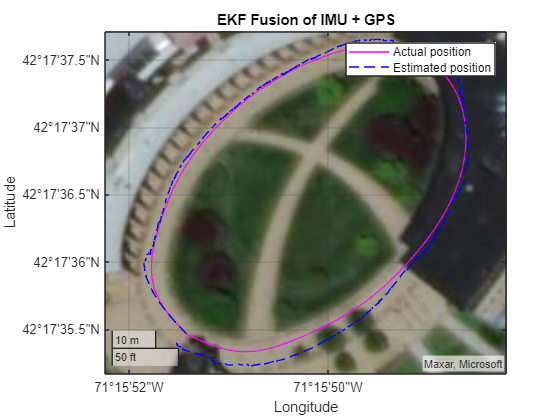

pos_est = [estPosition(:,1) estPosition(:,2) zeros(size(estPosition,1),1)];
pos_actual = [truePosition(:,1) truePosition(:,2) zeros(size(truePosition,1),1)];

[pos_est_lat,pos_est_lon,pos_est_alt] = local2latlon(pos_est(:,1), pos_est(:,2), pos_est(:,3), localOrigin);
[pos_actual_lat,pos_actual_lon,pos_actual_alt] = local2latlon(pos_actual(:,1), pos_actual(:,2), pos_actual(:,3), localOrigin);
geoplot(pos_actual_lat,pos_actual_lon, '-m');
hold on;
geoplot(pos_est_lat,pos_est_lon, '--b');
title("EKF Fusion of IMU + GPS");
legend({'Actual position', 'Estimated position'});
hold off;
geobasemap satellite;